# Explore **PASSIVE** rotations which Transform a G vec into a B vec

In this tutorial, we're going to explore the concept of **PASSIVE** rotation matrices. 

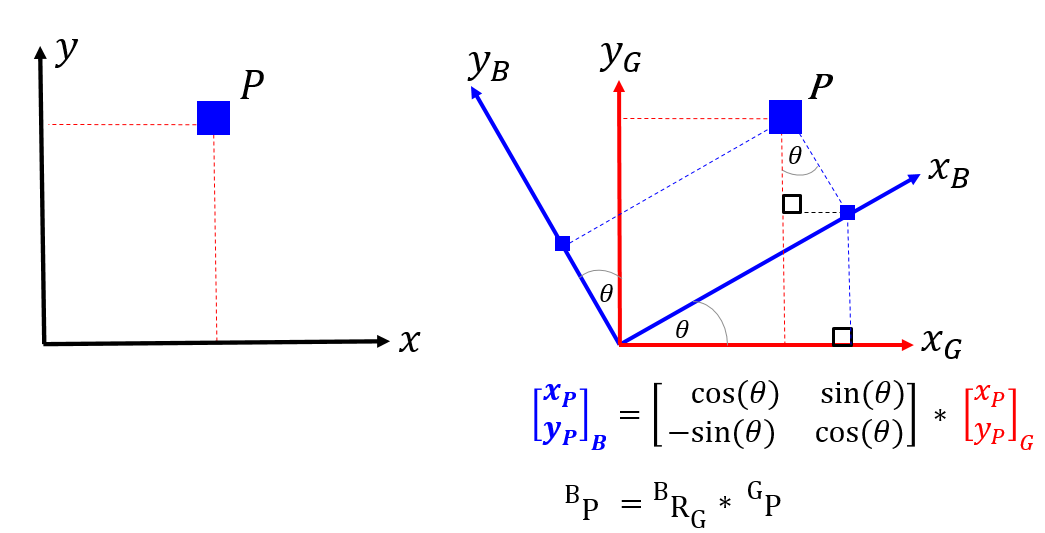

**Why are we doing this ?**

$\bullet $ Rotation matrices are used heavily in Mechanical, Robotic and Aeronautical engineering applications.

$\bullet $ Often students can get confused when they read the term "Rotation matrix".  In many/most cases, this confusion can be reduced by emphasizing a rotation matrix as being either PASSIVE or ACTIVE.

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

## Introduction:

## Introduction:

Consider the following scenario: 

$\bullet$ We have a data point $P$.

$\bullet$ We have a fixed frame called the **G-fame.**

$\bullet$ We know the *(x,y) *co-ordinates of the point $P$ in this **G-fame** and refer to this as ${^GP}$.

$\bullet$ We then rotate the **B-frame** relative to the fixed **G-frame**. 

$\bullet$ We now want to know what the co-ordinate of the point $P$ is relative to this new **B-frame, **ie: what is ${^BP}$ ?

This scenario is shown in the figure below:

 

A **PASSIVE** rotation matrix, converts the co-ordinates of a point expressed in a fixed **G-frame**, into the co-ordinates of the same point expressed in the new **B-frame**. 

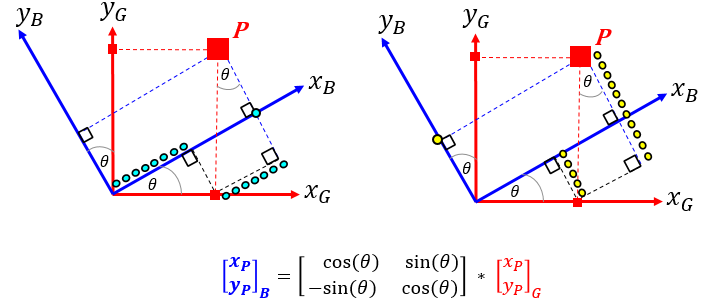

## An example of 3 successive PASSIVE rotations

Say we start with a G-frame. We're going to apply 3 LOCAL axes rotations which will result in a newly orientated frame called the B-frame.

Assume that we apply these 3 successive rotations in the following order:

- R1Z occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- R3X occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

We can express a vector defined in the G axis to it's corresponding description in the B axis, using a sequence of **PASSIVE** rotation matrices, ie:


$$\bf ^Bv = R3X(\psi_x) \enspace \times \enspace 
R2Y(\theta_y) \enspace \times \enspace R1Z(\phi_z) \enspace \times \enspace {^Gv}$$


    OR, in a more compact form as:


$$\bf ^Bv = {^BR_G} \enspace \times \enspace {^Gv}$$


## Create a passive rotation object

OBJ_A = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, [30 20 10],'DEGREES')

## Here are the PASSIVE rotation matrices

R1 = OBJ_A.get_R1
R2 = OBJ_A.get_R2
R3 = OBJ_A.get_R3

## Here are some compound rotation matrices

R2R1       = OBJ_A.get_R2R1

diff_mat   = R2R1 - R2*R1  % this should be zero

R3R2R1     = OBJ_A.get_R3R2R1

diff_mat_B = R3R2R1 - R3*R2*R1 % this should be zero

## Convert a vector in G, into its components in B

vG    = [1,0,0]';
vB = OBJ_A.apply_R3R2R1(vG)

diff_v = vB - R3*R2*R1*vG % this should be ZERO

## You can also supply SYMBOLIC angles

OBJ_B = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, [sym('phi'), sym('theta'), sym('psi')], 'SYM')

## the symbolic PASSIVE rotation matrices

R1 = OBJ_B.get_R1
R2 = OBJ_B.get_R2
R3 = OBJ_B.get_R3

## some symbolic compound rotation matrices

bRg = OBJ_B.get_R3R2R1